%%EJERCICIO 2
fx = @(t) 1+3*t.^2;
fy = @(t) 2*t+3*t.^3;

%Posiciones cada 1 seg
vectt = 0:1:100;

posx = fx(vectt);
posy = fy(vectt);

%Desplazamiento
fx10 = fx(10);%Coordenadas en t=10
fy10 = fy(10);

fx20 = fx(20);%Coordenadas en t=20
fy20 = fx(20);

%El desplazamiento estara dado por la distancia entre las coordenadas en
%t=10 y t=20

disp('Desplazamiento')

Desplazamiento


desp = sqrt(((fx20-fx10).^2)+((fy20-fy10).^2))

desp = 2.0295e+03



%Velocidad promedio
dift = 20-10;
difx = fx20-fx10;
dify = fy20-fy10;

difr = [difx dify];

disp('Velocidad Promedio')

Velocidad Promedio


velPromedio = difr/dift

velPromedio =    90.0000 -181.9000



%Aceleracion instantanea: derivando tenemos
aInstx = 6;
aInsty = @(t) 18*t;

disp('Aceleracion Instantanea en t=50')

Aceleracion Instantanea en t=50


aInst50 = [6 aInsty(50)]

aInst50 =      6   900



%Desplazamiento del dron
% for x=1:length(posx)
%     for y=1:length(posy)
%         plot(posx(x),posy(y),'.');  
%     end
% end


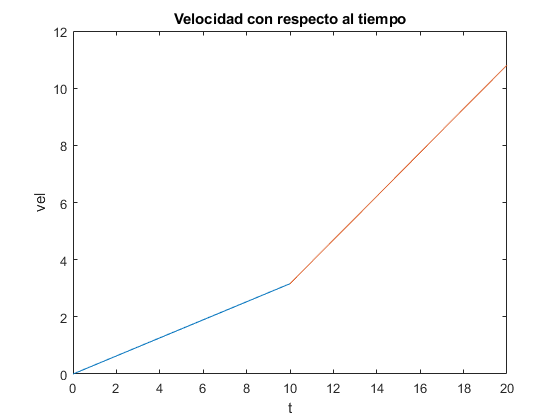

%EJERCICIO 1
v10 =@(t) 0.316*t;
v20 =@(t) 0.765*t-4.49;

t1 = 0:1:10;
t2 = 10:1:20;

plot(t1,v10(t1));
hold on
plot(t2,v20(t2));

xlim([0.0 20.0])
ylim([0.0 12.0])
title('Velocidad con respecto al tiempo')
xlabel('t')
ylabel('vel')

%Dinamico

for k = 1:length(t1)
    plot(t1(k),v10(t1(k)))
    pause(0.1);
    hold on
end
for k = 1:length(t2)
    plot(t2(k),v20(t2(k)))
    pause(0.1);
    hold on
end
xlim([0.0 20.0])
ylim([0.0 12.0])
title('Velocidad con respecto al tiempo')
xlabel('t')
ylabel('vel')